# Linear regression, GLMs and model comparison

To explore the distinctive firing patterns exhibited by individual hippocampal neurons in response to specific locations, a variety of approaches can be employed. These approaches enable us to create models that illustrate how neural activity relates to the animal's position. Learning how to model hippocampal place cell activity equips you with a versatile technique applicable to studying neuronal firing in response to external stimuli within other brain regions.

Given the complexity of neural activity and its susceptibility to various factors, certain models may capture these intricacies more effectively. Model comparisons offer a quantitative way to assess how well each model explains observed data. The goal of model comparison is to pinpoint which model strikes the right balance between simplicity and accuracy. It helps us avoid issues like overfitting (when a model fits noise in the data) or underfitting (when a model oversimplifies the underlying pattern). Ultimately, model comparisons guide us in selecting the model that yields the most valuable insights into how neurons process information and contribute to the brain's functions.

This tuorial is divided into three parts:

- mapping place fields under a linear model assumption

- mapping the selectivity of place cells with a generalized linear model approach

- comparison of place fields across experiemntal conditions

## 2.1. Mapping place fields, under a linear model assumption

This is the most common method used to estimate place fields (the location where a single place field fire). It consists in a series of steps which aim to compute the average firing rate of a place cell as a function of the positions of the animal. FYou have already been familiarized with these step in tutorial 1: first, behavioral data, which tracks the movement of the animal, is synchronized with the corresponding neural activity. Then, the environment is divided into discrete spatial bins. Each bin represents a small area within the environment. The size of the bins can vary depending on the resolution you desire for your place fields. Finally, the count of spikes that occurred when the animal was within a specific bin is tallied (see function ***Compute1DMap*** and ***Compute2DMap***). This count is then divided by the amount of time the animal spent in that particular bin (*occupancy map*). To create a clearer visualization, maps are usually smoothed with a gaussian (see ***GaussianSmooth***). This smoothing reduces noise and provides a smoother transition between adjacent spatial bins. 

*To identify place fields, observe regions on the heatmap where the neuron's firing rate is significantly higher which is assessed by a statistical approach.*

*The anallyses described in this section can be run by calling the following set of functions:*

%define parameters for place fields estimation
mapsparams = DefineMapsParams(Nav,Spk);

%change parameters here if necessary

%estimate 1D place fields and related statistics
Maps1D = MapsAnalyses1D(Nav, Spk.spikeTrain, mapsparams);

%estimate 2D place fields and related statistics
Maps2D = MapsAnalyses2D(Nav, Spk.spikeTrain, mapsparams);

*Some useful function that you will also find here are: ***Compute1DMap.m, GaussianSmooth1D.m**, **Compute2DMap.m, GaussianSmooth2D.m**

#### 2.1.1 Loading and preprocessing the behavioral and spiking data as done in Tutorial1

%Path to the directory where the data are stored
datadirpath = [filesep 'MATLAB Drive' filesep 'School' filesep 'Dataset' filesep 'Session1'];

%Load the default parameters for loading the data
loadparams = DefineLoadParams(datadirpath);

%Load the behavioral data into a matlab structure.
Nav = LoaddataNav(loadparams);

%Load the spiking data into a matlab structure.
Spk = LoaddataSpk(loadparams, Nav.sampleTimes);

#### 2.1.2 Parameters for estimating place fields

Defining a set of parameters needed to compute place fields such as the bin size used for discretizing the X variable or the experiemental conditions over which place fields should be estimated.

%Experimental conditions over which place fields will be estimated
mapsparams.condition = [1 3 5];

%Directions over which place fields will be estimated
mapsparams.dir = [-1 1];

%lap types over which place fields will be estimated
mapsparams.laptype = [-1 0 1];

%Minimum speed threshold over which place fields will be computed
mapsparams.spdthreshold = 2.5;

%Subset of cells for which place fields will be computed
mapsparams.cellidx = true(1, size(Spk.spikeTrain, 2));

%Sampling rate of the data
mapsparams.sampleRate = 1 / mean(diff(Nav.sampleTimes));

%Name of the field in the structure Nav that we will use as X dependent
%variable
mapsparams.Xvariablename = 'Xpos';

%Range of positions over which place fields will be estimated (in cm).
mapsparams.Xrange = [0 100];

%Size of the position bins (in cm).
mapsparams.Xbinsize = 4;

%Size of the gaussian window for smoothing place fields (in cm).
mapsparams.Xsmthbinsize = 2;

%Size of the gaussian window for smoothing place fields (in bins).
mapsparams.XsmthNbins = mapsparams.Xsmthbinsize / mapsparams.Xbinsize;

%Edges of position bins used to discretize positions
mapsparams.Xbinedges = mapsparams.Xrange(1):mapsparams.Xbinsize:mapsparams.Xrange(2);

%Occupancy threshold above which positions are included in the place field
%estimate (in seconds)
mapsparams.occ_th = 0;

%Minimal number of spikes to consider a cell
mapsparams.nspk_th = 0;

%Number of shuffle controls to perform
mapsparams.nShuffle = 100;

%Number of folds to consider for cross-validation
mapsparams.kfold = 10;

This set of parameters can be obtained by calling **DefineMapsParams.m**

mapsparams = DefineMapsParams(Nav,Spk);

#### 2.1.3 Compute place fields for all neurons (1D)

We will start by focusing on place fields when the animal is moving from left to right.

If you remember things from Tutorial 1, we first need to subset the data and keep only indices that correspond to the condition and criteria that we defined in mapsparams.

%We want left to right direction (Nav.Xdir = 1) so let's first change this
%parameter in the mapsparams structure. (We had [-1 1] originally.
mapsparams.dir = 1;

%Selecting time over which to compute place fields
tidx = ismember(Nav.Condition, mapsparams.condition) &...
       ismember(Nav.XDir, mapsparams.dir) &...
       ismember(Nav.laptype, mapsparams.laptype) &...
       Nav.Spd >= mapsparams.spdthreshold &...
       ~isnan(Nav.Xpos);

%Selecting cell indices for which we'll run the analysis
cellidx = find(mapsparams.cellidx & sum(Spk.spikeTrain(tidx,:), 1) > mapsparams.nspk_th);

%Subsetting Spk.spikeTrain and Nav.Xpos
spikeTrain = Spk.spikeTrain(tidx,cellidx);
Xpos = Nav.Xpos(tidx);

Then, we have to compute the occupancy map as done in Tutorial1, using **Compute1DMap.m** and **GaussianSmooth1D.m**

%number of position bins
nbins = numel(mapsparams.Xbinedges) - 1;

%Discretizing position vectors according to mapsparams.binedges
Xpos_discrete = discretize(Xpos, mapsparams.Xbinedges);

%Computing occupancy map (same for all cells)
flat =  1/mapsparams.sampleRate * ones(size(Xpos_discrete));
occmap = Compute1DMap(Xpos_discrete, flat, nbins);

%Removing occupancy for positions below the occupancy threshold
occmap(occmap <= mapsparams.occ_th) = NaN;

%Smoothing the occupancy map with a gaussian window (mapsparams.smthNbins
%of sd)
occmap = GaussianSmooth1D(occmap, mapsparams.XsmthNbins);

Now, we compute the spike count maps, using **Compute1DMap.m** and **GaussianSmooth1D.m**

%number of cells selected for place field analysis
ncells = size(spikeTrain, 2);

%Initializing the spike count map
scmap = NaN(ncells, nbins);

%Computing and smoothing spike count map for each cell
for icell = 1:ncells
    %raw spike count map
    scmap(icell,:) = Compute1DMap(Xpos_discrete, spikeTrain(:,icell), nbins);
    %Removing values of scmap where occupancy is too low
    scmap(icell,isnan(occmap)) = NaN;
    %Smoothing with a Gaussian (mapsparams.XsmthNbins of s.d.)
    scmap(icell,:) = GaussianSmooth1D(scmap(icell,:), mapsparams.XsmthNbins);
end

Finally, calculate the place field of all cells from the spike count maps (scmap) and the occupancy maps (occmap).

%Calculating the place field maps by dividing scmap and occmap
mapX = scmap ./ occmap;

This method to estimate place fields can be run by calling **MapsAnalyses1D.m**, which returns results of this place field estimation into a structure. 

Use that function to compute place fields for left to right and right to left directions.

%Computing left to right place fields
%Changing mapsparams.dir for left to right direction
mapsparams.dir = 1;

%Running the complete 1D map analysis
Maps1 = MapsAnalyses1D(Nav, Spk.spikeTrain, mapsparams);

%Same for right to left place fields
%Changing mapsparams.dir for left to right direction
mapsparams.dir = -1;
%Running the complete 1D map analysis
Maps2 = MapsAnalyses1D(Nav, Spk.spikeTrain, mapsparams);

We will now take the place fields of all cells and order them according to their peak position of firing. For visualization purpose, we will normalize maps between 0 and max firing rate. This helps us create what we call population spatial maps. These maps offer a complete picture of how place cells act all over the recording area. As we carried out our analysis independently for both rightward and leftward movements, this illustrates that place cells can exhibit spatial activity that is specific to particular directions

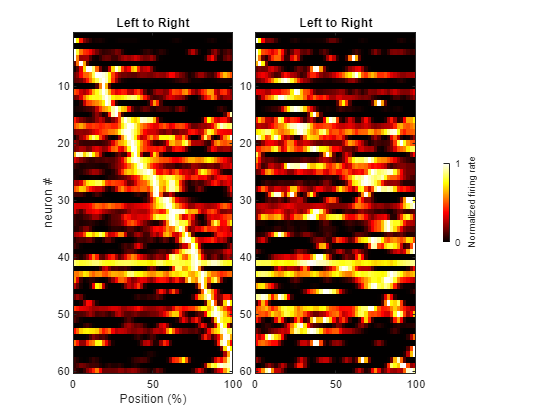

%Detecting max firing rate and peak position
[maxLtoR, peakidx] = max(Maps1.mapX, [], 2);
[maxRtoL, ~] = max(Maps2.mapX, [], 2);

%Normalizing place fields from 0 to max firing rate
mapXLtoR = Maps1.mapX ./ maxLtoR;
mapXRtoL = Maps2.mapX ./ maxRtoL;

%Reordering place fields according to peak position (estimated from L to R
%place fields).
[~, sortidx] = sort(peakidx, 'ascend');
mapXLtoR = mapXLtoR(sortidx,:);
mapXRtoL = mapXRtoL(sortidx,:);

%Plotting place fields side by side
figure;
bincenters = mapsparams.Xbinedges(1:end-1) + mapsparams.Xbinsize / 2;
subplot(1,5,[1 2]);
imagesc(bincenters, [], mapXLtoR);
subplot(1,5,[3 4]);
imagesc(bincenters, [], mapXRtoL);
colormap(hot);

%labels title etc
subplot(1,5,[1 2]);
xlabel('Position (%)');
ylabel('neuron #');
title('Left to Right');

subplot(1,5,[3 4]);
title('Left to Right');

subplot(3,5,10);
set(gca,'Visible','off')
c = colorbar('Ticks', [0 1], 'location', 'west');

c.Label.String = 'Normalized firing rate';

### 2.1.4 Compute place fields for all neurons (2D)

Mapping place fields in two dimensions, as opposed to a single dimension, offers a more comprehensive and nuanced understanding of the  encoding of spatial components by place cells. Such multidimensional place field mapping provides a more holistic view of how neurons encode multiple variable together. For instance, in a 2D arena, incorporating both X and Y axes is crucial in estimating how place cells encode positions (see Tutorial 1). Here, we will estimate the place fields of our neurons along X posiitons and directions of movement, all at once. The procedure is a very simple extension of the 1D case detailed above, so we will go quickly through it.

Just as before, we first start by subsetting Nav.Xpos, Nav.XDir and Spk.spikeTrain according to the criteria defined in mapsparams

%Now we'll take into account both directions of travel so we change
%mapsparams.dir accordingly
mapsparams.dir = [-1 1];

%Selecting time and cell indices over which to compute place fields
tidx = ismember(Nav.Condition, mapsparams.condition) &...
       ismember(Nav.XDir, mapsparams.dir) &...
       ismember(Nav.laptype, mapsparams.laptype) &...
       Nav.Spd >= mapsparams.spdthreshold &...
       ~isnan(Nav.Xpos);
   
cellidx = find(mapsparams.cellidx & sum(Spk.spikeTrain(tidx,:), 1) > mapsparams.nspk_th);

%Subsetting spikeTrain, Xpos and XDir.
spikeTrain = Spk.spikeTrain(tidx,cellidx);
Xpos = Nav.Xpos(tidx);
Dir = Nav.XDir(tidx);

Then we compute the occupancy maps as done previously, but this time using** Compute2DMap.m **and **GaussianSmooth.m**

%number of position bins
nXbins = numel(mapsparams.Xbinedges) - 1;

%number of direction bins
nLRbins = 2;

%No smoothing across directions
LRsmthNbins = 0;

%Discretizing position vectors according to mapsparams.Xbinedges
Xpos_discrete = discretize(Xpos, mapsparams.Xbinedges);

%Discretizing XDir so that 2 corresponds to left to right (ie
%Nav.XDir = 1) and 1 corresponds to right to left (ie Nav.XDir = -1).
Dir_discrete = NaN(size(Dir));
Dir_discrete(Dir == -1) = 1;
Dir_discrete(Dir == 1) = 2;

%Computing occupancy map (same for all cells)
flat =  1/mapsparams.sampleRate * ones(size(Xpos_discrete));
occmap = Compute2DMap(Dir_discrete, Xpos_discrete, flat, nLRbins, nXbins);

%Removing occupancy for positions below the occupancy threshold
occmap(occmap <= mapsparams.occ_th) = NaN;

%Smoothing the occupancy map with a 2D gaussian window
occmap = GaussianSmooth(occmap, [mapsparams.XsmthNbins LRsmthNbins]);

Now computing the spike count maps in a similar fashion.

%number of cells selected for place field analysis
ncells = size(spikeTrain, 2);

%Initializing the spike count map
scmap = NaN(ncells, nXbins, nLRbins);

%Computing and smoothing spike count map for each cell
for icell = 1:ncells
    scmap(icell,:,:) = Compute2DMap(Dir_discrete, Xpos_discrete, spikeTrain(:,icell), nLRbins, nXbins);
    scmap(icell,isnan(occmap)) = NaN;
    scmap(icell,:,:) = GaussianSmooth(squeeze(scmap(icell,:,:)), [mapsparams.XsmthNbins LRsmthNbins]);
end

Finally, calculating the place field of all cells by dividing the spike count map (scmap) with the occupancy (occmap).

%Calculating the place field x direction maps by dividing scmap and occmap
occmap = permute(occmap, [3 1 2]);%permuting dimension for element-wise division
mapXY = scmap ./ occmap;
occmap = squeeze(occmap);%reshaping occmap as before

All this code can be run by calling **MapsAnalyses2D.m**

mapsparams = DefineMapsParams(Nav,Spk);
Maps = MapsAnalyses2D(Nav, Spk.spikeTrain, mapsparams);

Have a look at the Maps structure returned by **MapsAnalyses2D.m **and find out where are the maps (You can use the help).

To make sure that we did everything correct, let's plot again the population place fields in both direction (same code as for the previous figure).

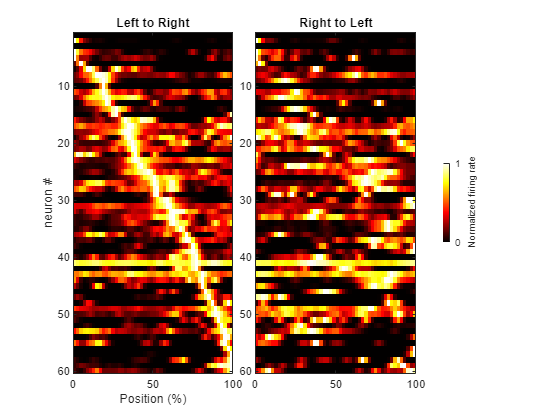

%Detecting max firing rate and peak position
[maxLtoR, peakidx] = max(Maps.mapXY(:,:,2), [], 2);
[maxRtoL, ~] = max(Maps.mapXY(:,:,1), [], 2);

%Normalizing place fields from 0 to max firing rate
mapXLtoR = Maps.mapXY(:,:,2) ./ maxLtoR;
mapXRtoL = Maps.mapXY(:,:,1) ./ maxRtoL;

%Reordering place fields according to peak position (estimated from L to R
%place fields).
[~, sortidx] = sort(peakidx, 'ascend');
mapXLtoR = mapXLtoR(sortidx,:);
mapXRtoL = mapXRtoL(sortidx,:);

%Plotting place fields side by side
figure;
bincenters = mapsparams.Xbinedges(1:end-1) + mapsparams.Xbinsize / 2;
subplot(1,5,[1 2]);
imagesc(bincenters, [], mapXLtoR);
subplot(1,5,[3 4]);
imagesc(bincenters, [], mapXRtoL);
colormap(hot);

%labels title etc
subplot(1,5,[1 2]);
xlabel('Position (%)');
ylabel('neuron #');
title('Left to Right');

subplot(1,5,[3 4]);
title('Right to Left');


subplot(3,5,10);
set(gca,'Visible','off')
c = colorbar('Ticks', [0 1], 'location', 'west');
c.Label.String = 'Normalized firing rate';

### 2.1.5 Place field significance

The next step involves quantifying the selectivity of place fields using key metrics. These metrics offer quantitative insights into how neurons respond to spatial locations. The* spatial information* metric assesses the neuron's encoding of location, while the *sparsity* of the tuning curve gauges how concentrated the firing pattern is around a particular spot. The *modulation index *captures the strength of selectivity in the firing pattern, and the *directionality index* evaluates preference for movement directions. To calculate these metrics, we'll use the following functions (**SpatialInfo.m**, **FieldSparsity.m**, **FieldSelectivity.m**, **FieldDirectionality.m**).

%Initilizing the vectors
SI = NaN(ncells, 1);
SparsityIndex = NaN(ncells, 1);
SelectivityIndex = NaN(ncells, 1);
DirectionalityIndex = NaN(ncells, 1);

%Calculating all metrics for each cell
for icell = 1:ncells
    SI(icell) = SpatialInfo(mapXY(icell,:,:), occmap);
    SparsityIndex(icell) = FieldSparsity(mapXY(icell,:,:), occmap);
    SelectivityIndex(icell) = FieldSelectivity(mapXY(icell,:,:));
    DirectionalityIndex(icell) = FieldDirectionality(mapXY(icell,:,1), mapXY(icell,:,2));
end

To measure the significance of the seletivity of a neurons to positions, we can now comparing the metrics obtained from the actual data with the same metrics measured after shuffling the spiking data with respect to positions. To maintain the original dynamics of shuffle control, we will permute the data by a random time delay. This process is repeated multiple times to create a distribution of random metrics. We then compare the metrics obtained from the actual cells with the statistically significant threshold determined by the distribution of random metrics.

%Computing shuffle controls by randomly shifting time bins of positions and
%calculate the selectivity metrics for each shuffle control

SI_Shf = NaN(ncells, mapsparams.nShuffle);
SparsityIndex_Shf = NaN(ncells, mapsparams.nShuffle);
SelectivityIndex_Shf = NaN(ncells, mapsparams.nShuffle);
DirectionalityIndex_Shf = NaN(ncells, mapsparams.nShuffle);

%Initializing the random number generator for reproducibility purposes
s = RandStream('mt19937ar','Seed',0);

%number of data points
ntimepts = size(spikeTrain, 1);

%Calculating the place field for each shuffle permutation
for iperm  = 1:mapsparams.nShuffle
    tshift = randi(s,ntimepts - 2 * mapsparams.sampleRate) + 1 * mapsparams.sampleRate;%(Check here)
    Xpos_discrete_shf = circshift(Xpos_discrete, round(tshift));%(Check here)
    Dir_discrete_shf = circshift(Dir_discrete, round(tshift));%(Check here)
    for icell = 1:ncells
        scmap_shf = Compute2DMap(Dir_discrete_shf, Xpos_discrete_shf, spikeTrain(:,icell), nLRbins, nXbins);
        scmap_shf(isnan(occmap)) = NaN;
        scmap_shf = GaussianSmooth(scmap_shf, [mapsparams.XsmthNbins LRsmthNbins]);
        mapX_shf = scmap_shf ./ occmap;
        
        %saving only the spatial selectivity metrics for each permutation
        SI_Shf(icell,iperm) = SpatialInfo(mapX_shf, occmap);
        SparsityIndex_Shf(icell,iperm) = FieldSparsity(mapX_shf, occmap);
        SelectivityIndex_Shf(icell,iperm) = FieldSelectivity(mapX_shf);
        DirectionalityIndex_Shf(icell,iperm) = FieldDirectionality(mapX_shf(:,1), mapX_shf(:,2));
    end
end

%Computing p-values from the distribution of selectivity measures obtained
%from the shuffle controls
SI_pval = sum(SI_Shf > SI, 2) / mapsparams.nShuffle;
SparsityIndex_pval = sum(SparsityIndex_Shf > SparsityIndex, 2) / mapsparams.nShuffle;
SelectivityIndex_pval = sum(SelectivityIndex_Shf > SelectivityIndex, 2) / mapsparams.nShuffle;
DirectionalityIndex_pval = sum(DirectionalityIndex_Shf > DirectionalityIndex, 2) / mapsparams.nShuffle;

Another way to assess the significance of those place fields is by estimating how much adding position to the model improves its ability to explain the neuron's response. This is called model comparison and it enables us to determine which model best captures the underlying patterns in the data. Cross-validation enhances the reliability of model comparison by rigorously assessing model performance on unseen data. By partitioning the dataset into training and testing subsets, cross-validation prevents overfitting, i.e. where a model may perform well on training data but poorly on new data. This approach ensures that the chosen model is not only adept at explaining the observed data but also generalizes well to new instances. Thus, conducting model comparison on cross-validated data provides a robust framework for selecting the most accurate and meaningful representation of complex neural processes.

As a first step, we thus need to compute spiking responses predicted by the place field model and to do so we will use a k-fold cross-validation apparoch. K-fold cross-validation is a method used to assess the performance of a model by dividing a dataset into "k" subsets. The model is trained on "k-1" subsets and tested on the remaining fold in each iteration. This process is repeated "k" times, allowing for a comprehensive evaluation of the model's predictive ability over the entire dataset.

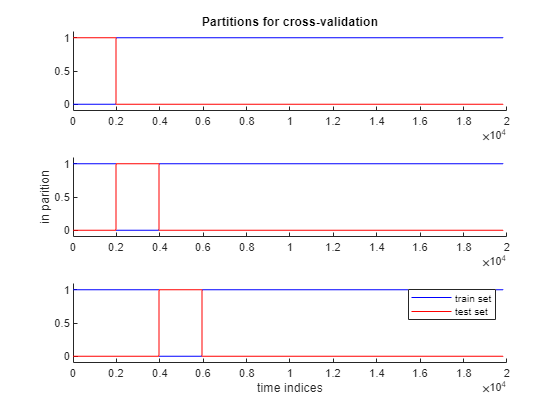

%Defining a partition of the data for k-fold cross-validation
cv = crossvalPartition(ntimepts, mapsparams.kfold);

%Plotting the first three partitions
figure;
for k = 1:3
    subplot(3,1,k);
    plot(cv.trainsets{k},'b');
    hold on;plot(cv.testsets{k},'r');
    set(gca,'Ylim',[-0.1 1.1],'box', 'off')
    if k == 3
        xlabel('time indices')
        legend({'train set', 'test set'})
    end
    if k == 2
        ylabel('in parition')
    end
    if k == 1
        title('Partitions for cross-validation')
    end
end

Now, we will calculate spike train predictions from place fields using this k-fold partition. To do that, we iterate through each fold, calculating the placef ields on data from the training sets and predicting the spike train from the place fields on the testsets.

Let's first estimate place fields on each training set from the k-fold partition. 

%Computing the spike train predicted from the place field using k-fold 
%cross-validation
mapXY_cv = NaN(ncells, nXbins, nLRbins, mapsparams.kfold);
for i = 1:mapsparams.kfold
    %Subsetting Xpos and spiketrain according to the train set of the
    %current fold
    Xtraining = Xpos_discrete(cv.trainsets{i});
    Dirtraining = Dir_discrete(cv.trainsets{i});
    Spktraining = spikeTrain(cv.trainsets{i},:);
    
    %Computing occupancy map for the current fold
    flat = 1/mapsparams.sampleRate * ones(size(Xtraining));
    occmap_cv = Compute2DMap(Dirtraining, Xtraining, flat, nLRbins, nXbins);
    occmap_cv(occmap_cv <= mapsparams.occ_th) = NaN;
    occmap_cv = GaussianSmooth(occmap_cv, [mapsparams.XsmthNbins LRsmthNbins]);
    
    %Computing the spike count map and place field of each cell for the
    %current fold
    for icell = 1:ncells
        scmap_cv = Compute2DMap(Dirtraining, Xtraining, Spktraining(:,icell), nLRbins, nXbins);
        scmap_cv(isnan(occmap_cv)) = NaN;
        scmap_cv = GaussianSmooth(scmap_cv, [mapsparams.XsmthNbins LRsmthNbins]);
        mapXY_cv(icell,:,:,i) = scmap_cv ./ occmap_cv;
    end
end

Now use the place fields computed from the train sets to predict the response on the test set for each fold

Ypred = NaN(ntimepts,ncells);
for i = 1:mapsparams.kfold
    %Subsetting Xpos and Dir according to the test set of the current fold
    Xtest = Xpos_discrete(cv.testsets{i});
    Dirtest = Dir_discrete(cv.testsets{i});
    
    %Computing the spike train predicted on the test set from the place 
    %computed from the train set
    for icell = 1:ncells
        XDiridx = sub2ind([ncells, nXbins, nLRbins, mapsparams.kfold], icell*ones(size(Xtest)), Xtest, Dirtest, i*ones(size(Xtest)));
        Ypred(cv.testsets{i},icell) = mapXY_cv(XDiridx) / mapsparams.sampleRate;%(Check here)
    end
end

Let's plot the predicted and actual responses for cell #18 together with the position of the animal for the first 40 seconds

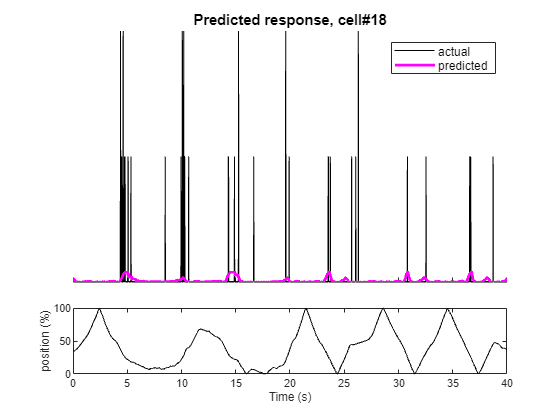

figure;
cellnum = 18;

%time indices of the first 40 seconds
idx = 1:40 * loadparams.sampleRate;

%Plotting predicted and actual responses
subplot(4, 1, 1:3);
plot(idx / loadparams.sampleRate, spikeTrain(idx,cellidx == cellnum),'k');
hold on;plot(idx / loadparams.sampleRate, Ypred(idx,cellidx == cellnum),'m', 'linewidth', 2);

%Plotting the position of the animal for the same time bins
subplot(4, 1, 4);
plot(idx / loadparams.sampleRate, Xpos(idx),'k');

%Legend, title, labels etc
subplot(4, 1, 1:3);
legend({'actual', 'predicted'})
set(gca,'Box','off', 'XtickLabel', [], 'Ytick',[], 'YColor', 'none')
title('Predicted response, cell#18')
subplot(4, 1, 4);
xlabel('Time (s)')
ylabel('position (%)')

Keep in mind that the ultimate objective of generating spike trains predicted by the place field model is to evaluate whether this model provides a more effective explanation for neural firing compared to a model that does not consider position as a predictor of the neuron's response. To achieve this, we must proceed by calculating the neuron's response under the assumption of a position-independent model, where the cell is assumed to exhibit a constant mean firing rate.

%Computing the spike train predicted from the mean firing rate of the 
%cell using the same k-fold partition as above
Ypred_cst = NaN(ntimepts,ncells);
for i = 1:mapsparams.kfold
    for icell = 1:ncells
        Ypred_cst(cv.testsets{i},icell) = nanmean(spikeTrain(cv.trainsets{i},icell));
    end
end

Compute the log likelihood for both the place field model and the constant mean model based on the predicted responses.

%Computing the percentage of explained variance and the log likelihood from
%the predicted responses.
EV = NaN(ncells,1);
LLH = NaN(ncells,1);
EV_cst = NaN(ncells,1);
LLH_cst = NaN(ncells,1);
for icell = 1:ncells
    %Percentage of explained variance for the place field model
    EV(icell) =  computeEV(spikeTrain(:, icell), Ypred(:, icell));
    %Log likelihood for the place field model
    LLH(icell) = computeLLH_normal(spikeTrain(:, icell), Ypred(:, icell));

    %Percentage of explained variance for the constant mean model
    EV_cst(icell) =  computeEV(spikeTrain(:, icell), Ypred_cst(:, icell));
    %Log likelihood for the constant mean model
    LLH_cst(icell) = computeLLH_normal(spikeTrain(:, icell), Ypred_cst(:, icell));
end

A method to assess the significance of incorporating positions into the model is to compare the log likelihood between the place field model and the constant mean model through a likelihood ratio test.

%Comparing the place field model to the constant mean model by performing a
%likelihood ratio test
LLH_pval = NaN(ncells,1);
goodidx = LLH > LLH_cst;
LLH_pval(~goodidx) = 1;

%difference of degree of freedom between the two models.
dof = sum(occmap(:) > 0) - 1;

%Likelihood ratio test for cells which have a higher LLH for the place
%field model (the other one are definitely not significant).
[~, LLH_pval(goodidx)] = lratiotest(LLH(goodidx), LLH_cst(goodidx), dof);

A valuable aspect of having computed the cross-validated place fields is the ability to derive a Jackknife estimate of the standard error from the k-fold cross-validated place fields. This estimation is based on assessing the difference between  place field of each individual fold and the overall mean place field. 

%Computing the Jacknife estimate of the standard error
mapXY_SE = sqrt((mapsparams.kfold - 1)./mapsparams.kfold * sum((mapXY_cv - mapXY).^2, 4));

All this code is also run in **MapsAnalyses2D.m**. 

Have a look at the Maps structure returned by **MapsAnalyses2D.m, **find out where these statistics are stored adn estimate the fraction of pyramidal cells that have a significant significant place field in terms of prediction accuracy.

Plot the place fields of neurons that are significant and those that are not (using P-value = 0.05 as a threshold).

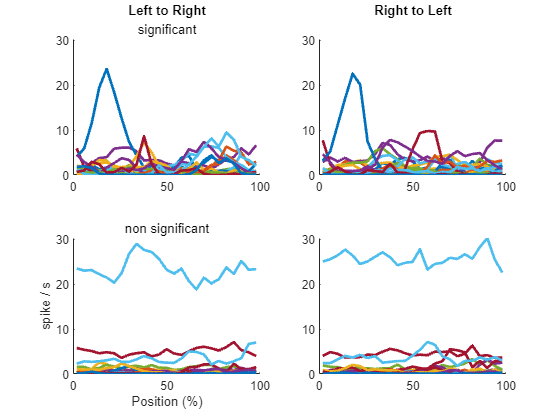

%Plotting place fields side by side
figure;
bincenters = mapsparams.Xbinedges(1:end-1) + mapsparams.Xbinsize / 2;
m = max(Maps.mapXY, [], 'all');

for idir = 1:2
    subplot(2,2,idir);
    plot(bincenters, squeeze(Maps.mapXY(Maps.LLH_pval <= 0.05,:,idir))','linewidth', 2);
    set(gca,'Ylim', [0 m],'Box', 'off');
end
for idir = 1:2
    subplot(2,2,idir + 2);
    plot(bincenters, squeeze(Maps.mapXY(Maps.LLH_pval > 0.05,:,idir))','linewidth', 2);
    set(gca,'Ylim', [0 m],'Box', 'off');
end

%labels title etc
subplot(2,2,3);
xlabel('Position (%)');
ylabel('spike / s');
subtitle('non significant')

subplot(2,2,1);
title('Left to Right');
subtitle('significant')

subplot(2,2,2);
title('Right to Left');
subtitle(' ')

Generate plots depicting the place fields and their associated standard errors for the initial two significant cells, as well as for the non-significant cells.

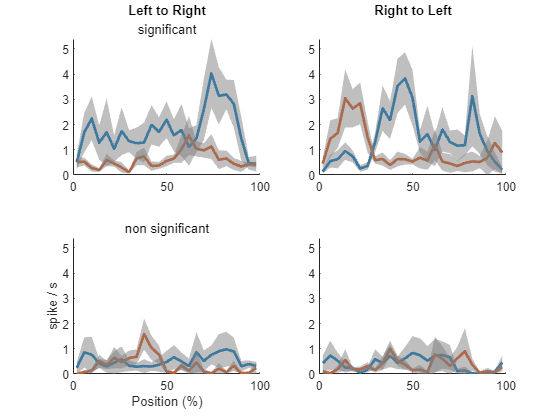

%indices of cells to plot
cellnum1 = find(Maps.LLH_pval <= 0.05, 2, 'first');
cellnum2 = find(Maps.LLH_pval > 0.05, 2, 'first');
m = max(Maps.mapXY([cellnum1(:)' cellnum2(:)'],:,:) + Maps.mapXY_SE([cellnum1(:)' cellnum2(:)'],:,:), [], 'all');

%Plotting place fields side by side
figure;
bincenters = mapsparams.Xbinedges(1:end-1) + mapsparams.Xbinsize / 2;

for idir = 1:2
    subplot(2,2,idir);
    plot(bincenters, squeeze(Maps.mapXY(cellnum1,:,idir))', 'linewidth', 2);
    hold on;ciplot(bincenters, squeeze(Maps.mapXY(cellnum1,:,idir) - Maps.mapXY_SE(cellnum1,:,idir)), squeeze(Maps.mapXY(cellnum1,:,idir) + Maps.mapXY_SE(cellnum1,:,idir)))
    set(gca,'Ylim', [0 m],'Box', 'off');
end

for idir = 1:2
    subplot(2,2,idir + 2);
    plot(bincenters, squeeze(Maps.mapXY(cellnum2,:,idir))', 'linewidth', 2);
    hold on;ciplot(bincenters, squeeze(Maps.mapXY(cellnum2,:,idir) - Maps.mapXY_SE(cellnum2,:,idir)), squeeze(Maps.mapXY(cellnum2,:,idir) + Maps.mapXY_SE(cellnum2,:,idir)))
    set(gca,'Ylim', [0 m],'Box', 'off');
end

%labels title etc
subplot(2,2,3);
xlabel('Position (%)');
ylabel('spike / s');
subtitle('non significant')

subplot(2,2,1);
title('Left to Right');
subtitle('significant')

subplot(2,2,2);
title('Right to Left');
subtitle(' ')

Plot the place fields as colored maps

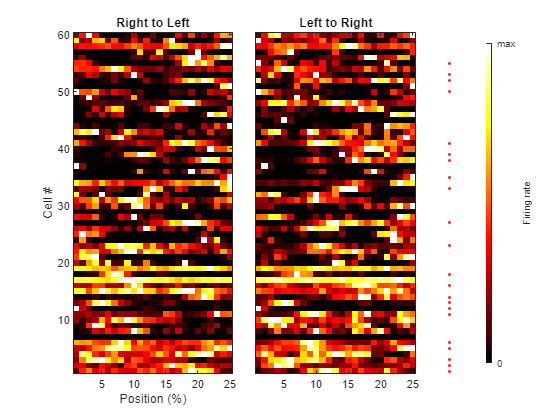

figure;

%for titling
dirnames = {'Right to Left', 'Left to Right'};

%Plotting place fields normalized to max activation rate
for idir = 1:2
    subplot(1,5,(idir-1)*2 + 1:idir*2);
    imagesc(Maps.mapXY(:,:,idir) ./ max(Maps.mapXY(:,:,idir), [], 2));
    set(gca,'Clim', [0 1], 'Ydir', 'normal');
    title(dirnames{idir})
    if idir == 1
        xlabel('Position (%)')
        ylabel('Cell #')
    end
    if idir == 2
        set(gca, 'Ytick', []);
    end
end
colormap(hot);

%Marking with an asterisk those with a significant place field.
subplot(1,10,9);
sigidx = find(Maps.LLH_pval <= 0.05);
plot(zeros(size(sigidx)), sigidx - 0.5, 'r.');
set(gca, 'Xtick', [], 'XColor', 'none', 'Ytick', [], 'YColor', 'none')

%Colorbar
subplot(1,10,10);
set(gca,'Visible', 'off')
c = colorbar('Location', 'west', 'Ticks', [0 1], 'TickLabels', {'0', 'max'});
c.Label.String = 'Firing rate';